# License Plate Recognition with MATLAB

Using basic image processing techniques, we can program a computer to read license plates and report the license number. This example shows how to process a license plate image to read the license number using MATLAB. The process involves:

- Convert the image to black-and-white (BW)

- Find the region of interest (ROI)

- Extract the image of each character

- Identify each character and report the license number

*Copyright © Angora Tutor, 2020. All rights reserved.*

## The App

Let's start with the License Plate Recognition App. Start the app, choose a license plate picture. You can see the original and gray scale. You can explore the effect of the threshold on the generated black and white image. You can also see the effect of the horizontal threshold on selecting the ROI and vertical threshold on the identification of the characters. 

LicensePlateRecognitionApp

The app is cool, but how does it all work? Keep on reading to learn the details!

## Read the Image and Preprocess

Read the license plate image into memory and display. Note that this is a 408x800 pixel color (RGB) image.

fileName = 'license_plate.jpg';
licensePlate = imread(fileName);
whos licensePlate

  Name                Size                Bytes  Class    Attributes

  licensePlate      408x800x3            979200  uint8              



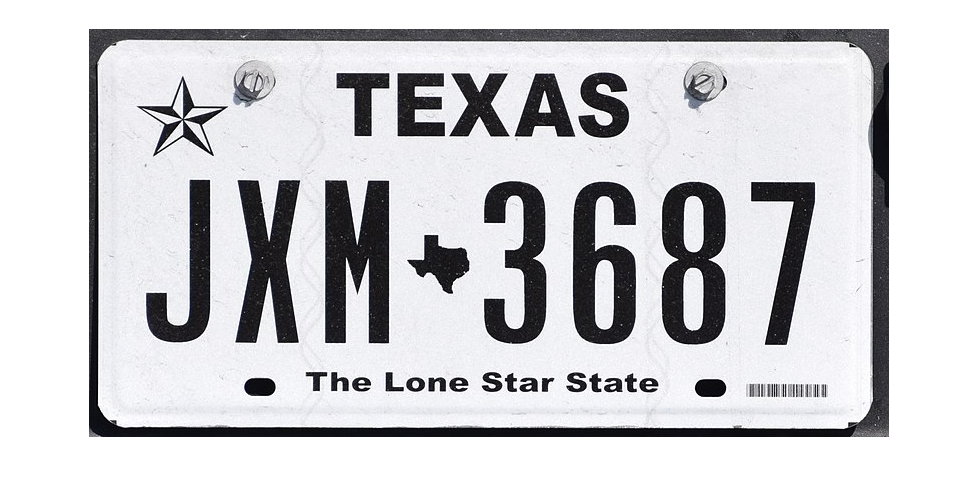

imshow(licensePlate)

Convert the image to gray scale. Now, for each pixel, we have an integer number between 0 and 255, where 0 represents black and 255 represent white.

licensePlateGray = rgb2gray(licensePlate);
max(licensePlateGray(:))

ans = uint8
255

min(licensePlateGray(:))

ans = uint8
0

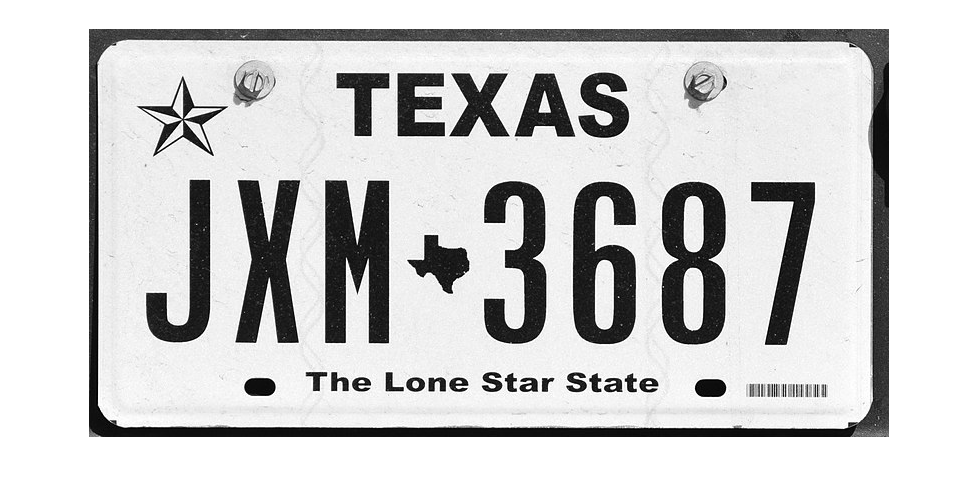

imshow(licensePlateGray)

Now convert the image into a BW image, which has only two value for each pixel: 0 for white and 1 for black. I chose this convention since the letters are the information we are looking for and they should have a value, while background has no information and should have a value of 0. We first need to decide on the threshold to convert the gray scale into black-and-white. Histogram of the pixel values helps us decide the best threshold value. 

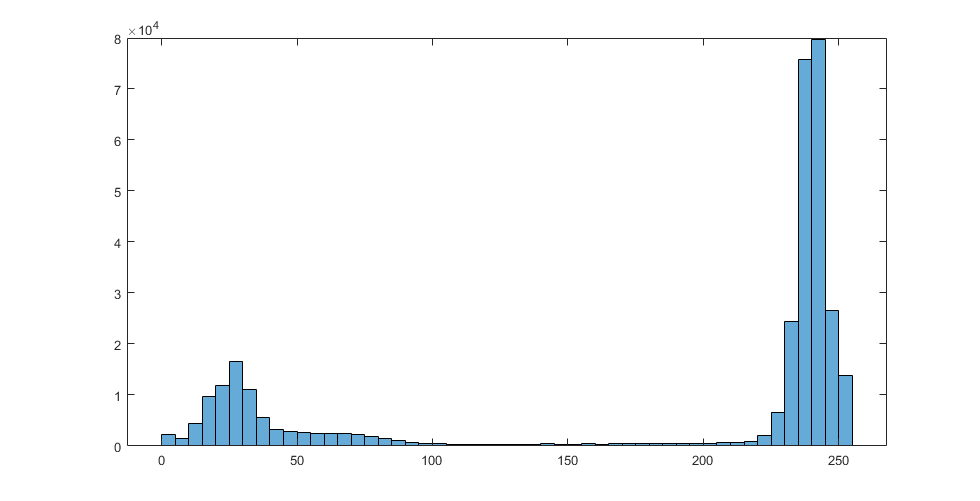

histogram(licensePlateGray)

threshold = 100;

There are two groups of pixels, one around 25 (dark regions) and one around 230 (light regions). 200 looks like a good threshold value. Note that, black regions correspond to light colored pixels in the original image and has a value of 0.

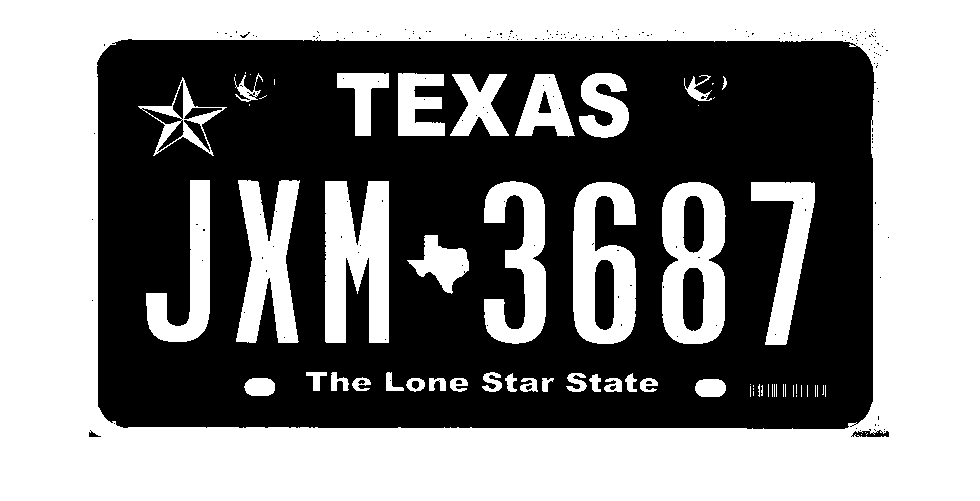

licensePlateBW = licensePlateGray < threshold;
imshow(licensePlateBW)

## Find Region of Interest (ROI)

Find where the letters and numbers of the license plate are. These are the characters we want to read. In this example license plate, the computer needs to identify the rows where these letters are. We call this also "region of interest" or ROI.

Let's start by exploring how we can find the upper and lower bounds of the characters. Plot the total number of white pixels on each row.

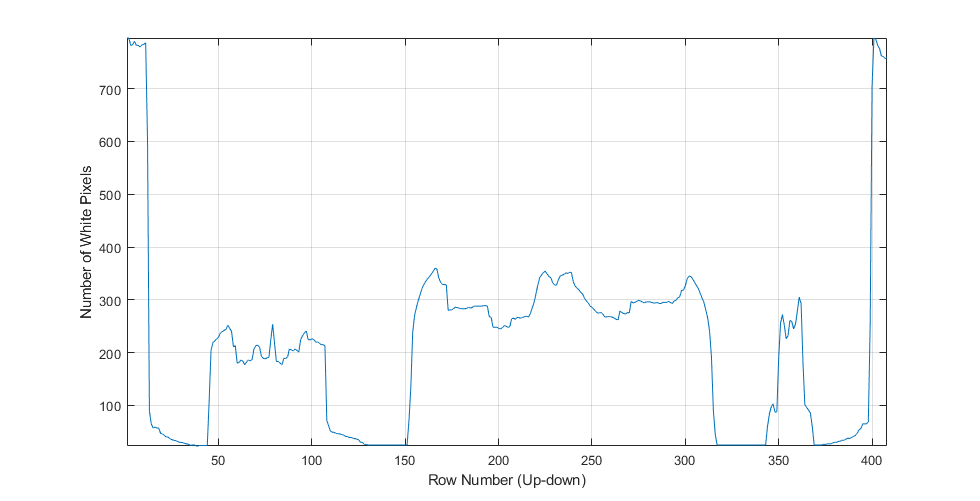

whiteCountPerRow = sum(licensePlateBW,2);
plot(whiteCountPerRow)
xlabel('Row Number (Up-down)')
ylabel('Number of White Pixels')
grid on
axis tight

This plot show us distinctive groups of row:

- 1-10: Upper border of the license plate

- 50-110: star and "Texas"

- 150-320: License number

- 350-375: "The lone star state"

- 400-408: Lower border of the license plate

The widest region is the ROI. So, let's find the largest region programmatically. We first need to define a threshold to indicate the presence of a group, which we will chose as 110.

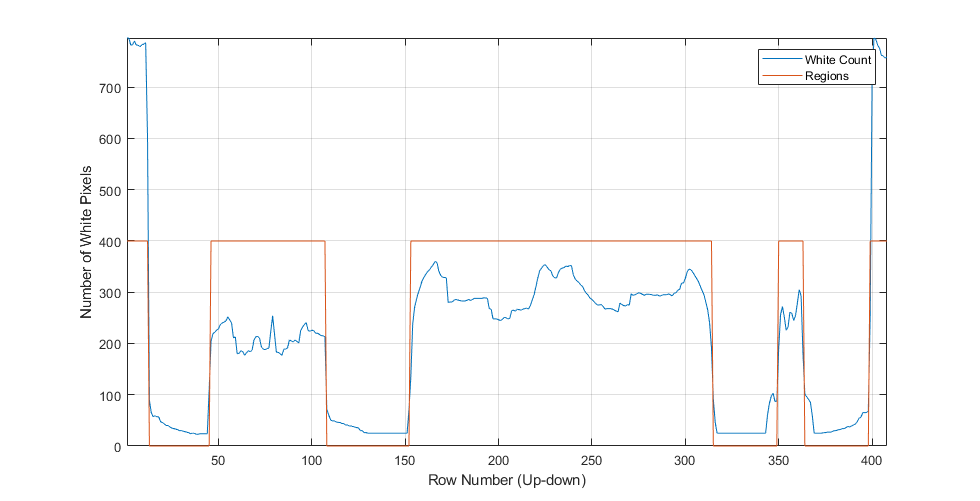

regions = whiteCountPerRow > 110;
plot(1:length(whiteCountPerRow), whiteCountPerRow)
hold on
plot(regions*400)
hold off
xlabel('Row Number (Up-down)')
ylabel('Number of White Pixels')
grid on
axis tight
legend('White Count', 'Regions')

We can find the transition points by taking the difference of consecutive values of the `regions` array. The 1 values are the starting point of regions of interest and -1 are the end point. First starting region has no +1 and the last region has no -1. So, we will add those manually.

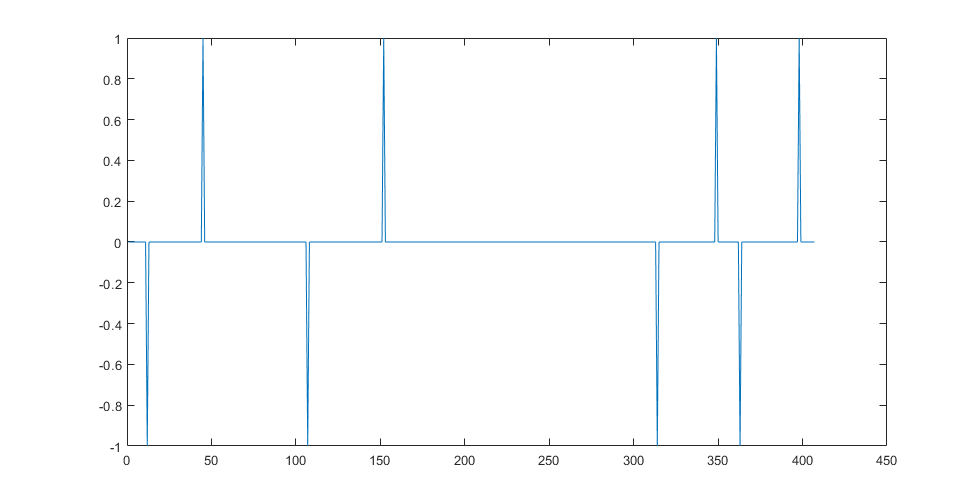

plot(diff(regions))

startIdx = [1; find(diff(regions)==1)]

startIdx =      1
    45
   152
   349
   398


endIdx = [find(diff(regions)==-1); length(regions)]

endIdx =     12
   107
   314
   363
   408


endIdx-startIdx

ans =     11
    62
   162
    14
    10


[~,widestRegionIdx] = max(endIdx-startIdx)

widestRegionIdx = 3

upperLimitROI = startIdx(widestRegionIdx)

upperLimitROI = 152

lowerLimitROI = endIdx(widestRegionIdx)

lowerLimitROI = 314

Crop the image from top and bottom.

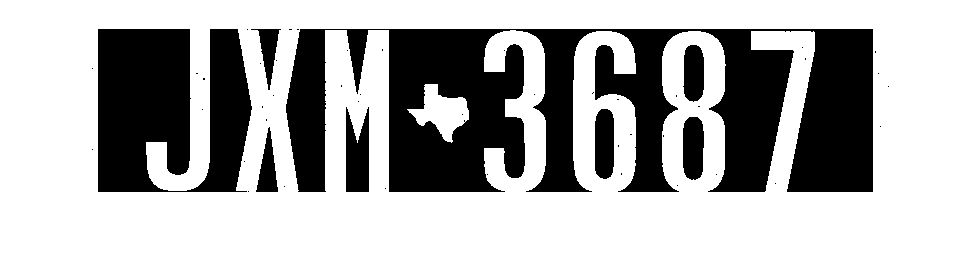

licensNumberROI = licensePlateBW(upperLimitROI:lowerLimitROI,:);
imshow(licensNumberROI)

## Find Individual Letters and Identify

In this ROI, find the individual letters and extract that part of the image. Identify the letter and record the results. Keep finding and identifying letters until all of them are processed. Ignore the Texas map symbol.

Now, let's do a similar processing to find the where the letters start and end. This time, we will explore the number of white pixels per column.

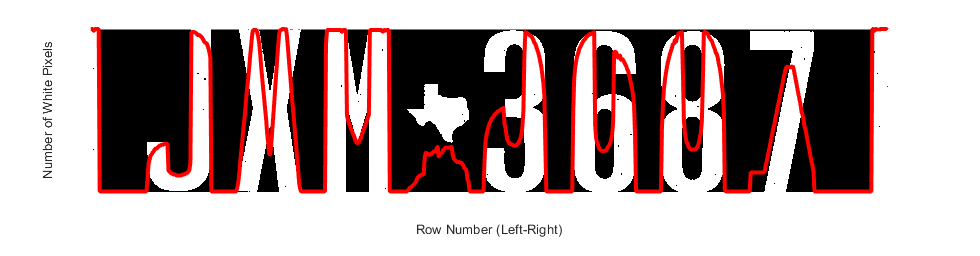

whiteCountPerColumn = sum(licensNumberROI,1);
imshow(licensNumberROI)
hold on
plot(max(whiteCountPerColumn) - whiteCountPerColumn,'r',"LineWidth",3)
xlabel('Row Number (Left-Right)')
ylabel('Number of White Pixels')
grid on
axis tight
hold off

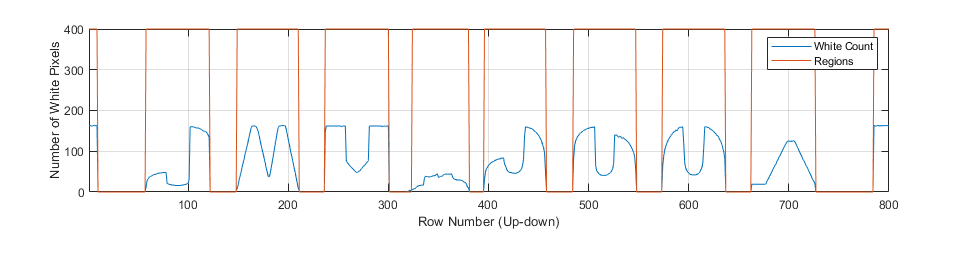

regions = whiteCountPerColumn > 5;

plot(whiteCountPerColumn)
hold on
plot(regions*400)
hold off
xlabel('Row Number (Up-down)')
ylabel('Number of White Pixels')
grid on
axis tight
legend('White Count', 'Regions')

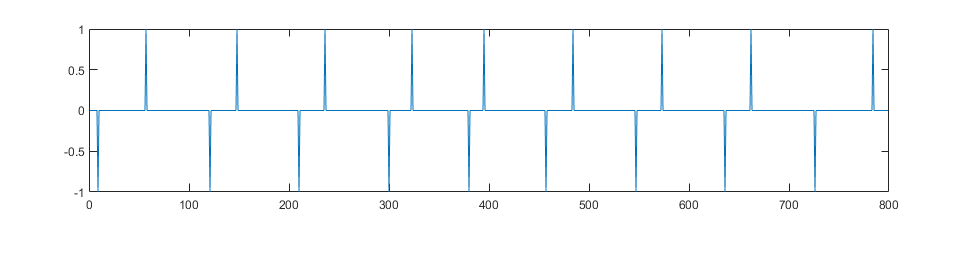

plot(diff(regions))

startIdx = [1 find(diff(regions)==1)]

startIdx =      1    57   148   236   323   395   484   573   662   784


endIdx = [find(diff(regions)==-1) length(regions)]

endIdx =      9   121   210   300   380   457   547   636   726   800


regions = endIdx-startIdx

regions =      8    64    62    64    57    62    63    63    64    16


Find the mean regions size. We will discard any regions that is narrower than this size to eliminate borders. 

widthThreshold = mean(regions)

widthThreshold = 52.3000

### Find the First Letter and Identify

Now, let's find the first letter. We know that the first region is border. So, the first letter is in the second region.

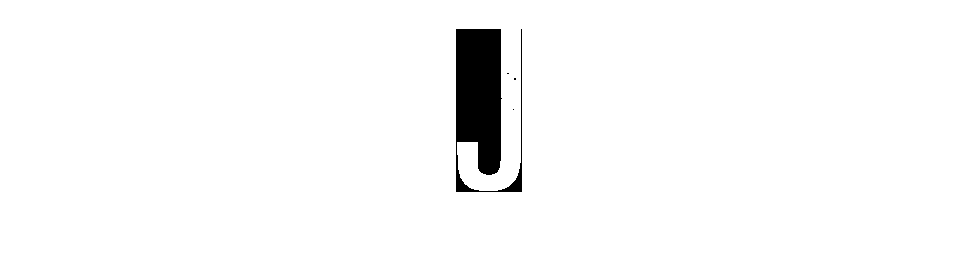

letterImage = licensNumberROI(:,startIdx(2):endIdx(2)+1);
imshow(letterImage)

Now, we need to find which one of the templates looks most similar to this letter. There are the template images.

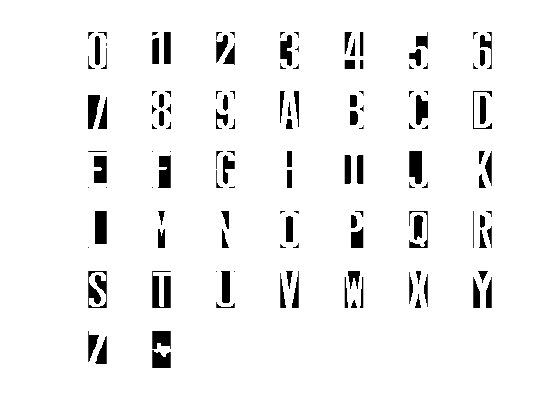

templateDir = fullfile(pwd,'templates');
templates = dir(fullfile(templateDir,"*.png"));

figure
candidateImage = cell(length(templates),2);
for p=1:length(templates)
    subplot(6,7,p)
    [~,fileName] = fileparts(templates(p).name);
    candidateImage{p,1} = fileName;
    candidateImage{p,2} = imread(fullfile(templates(p).folder,templates(p).name));
    imshow(candidateImage{p,2})
end

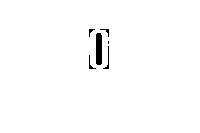

template1 = imread(fullfile(templates(1).folder,templates(1).name));
figure
imshow(template1)

We need to find a similarity or difference metric for these two images. A very common metric is the Euclidean distance. For scalars, or 1-D data, the distance is the absolute value of the difference. For example:

x = 1;
y = 4;
distance1D = abs(x-y)

distance1D = 3

For 2-D variables, we can use the following:

x = [1 2];
y = [4 -1];
temp = x - y;
distance2D = sqrt(abs(temp(1)^2 + temp(2)^2))

distance2D = 4.2426

For N-D variables, such as the one we have, where we need to compare multiple pixels, we use the following:

x = randi(10,1,4)

x =      1     9    10     7


y = randi(10,1,4)

y =      8     8     4     7


temp = x - y;
distanceND = sqrt(abs(sum(temp.^2)))

distanceND = 9.2736

Since square-root is a monotonically increasing function, we can omit it in our comparisons and just use the square of the distance. But first, we need to make sure that the two images are the same size.

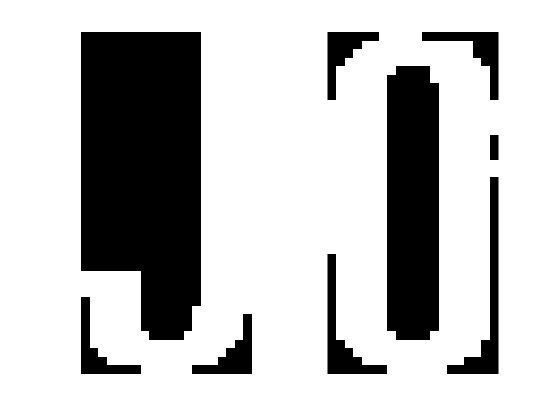

letterImage = imresize(letterImage,size(template1));
figure
subplot(1,2,1)
imshow(letterImage)
subplot(1,2,2)
imshow(template1)

distance = abs(sum((letterImage-double(template1)).^2,"all"))/numel(template1) %#ok<NASGU> 

distance = 0.3450

Now, let's do this for all the templates and find the minimum distance or the most likely letter:

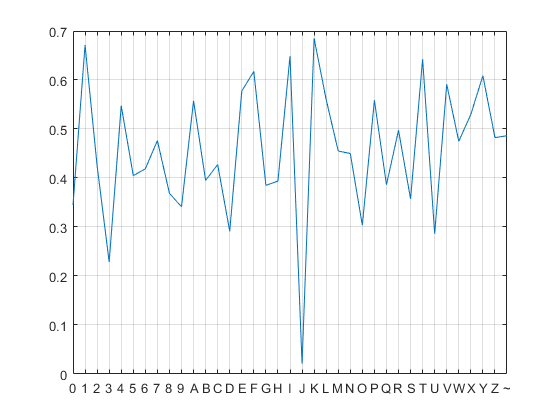

distance = zeros(1,length(templates));
for p=1:length(templates)
    distance(p) = abs(sum((letterImage-double(candidateImage{p,2})).^2,"all"))/numel(candidateImage{p,2});
end
figure
chars = ["0","1","2","3","4","5","6","7","8","9",...
   "A","B","C","D","E","F","G","H","I","J","K","L","M","N","O", ...
   "P","Q","R","S","T","U","V","W","X","Y","Z","~"];
plot(distance)
xticklabels(chars)
xticks(1:length(chars))
xlim([1 37])
grid on

[d,idx] = min(distance);
templates(idx)

ans = struct with fields:
       name: 'J.png'
     folder: 'C:\Users\emsoz\OneDrive - Angora Tutor\AngoraTutor\YouTube\LicensePlateRecognition\templates'
       date: '05-May-2020 07:59:09'
      bytes: 115
      isdir: 0
    datenum: 7.3792e+05


[~,letter] = fileparts(templates(idx).name)

letter = 'J'

### Find All the Letters and Identify

Now, it is time to put it all together and read the license plate.

licenseNumber = '';
for p=1:length(regions)
    if regions(p) > widthThreshold
        % Extract the letter
        letterImage = licensNumberROI(:,startIdx(p):endIdx(p));

        % Compare to templates
        distance = zeros(1,length(templates));
        for t=1:length(templates)
            letterImage = imresize(letterImage,size(candidateImage{t,2}));
            distance(t) = abs(sum((letterImage-double(candidateImage{t,2})).^2,"all"));
        end
        [d,idx] = min(distance);
        letter = candidateImage{idx,1};
        if strcmp(letter, 'map')
            letter = '~';
        end
        licenseNumber(end+1) = letter; %#ok<SAGROW> 
    end
end

## Report the Results

licenseNumber

licenseNumber = 'JXM~3687'